P = 0:3;
T = [0.0 2.0 4.1 5.9];
net = newgrnn(P,T,0.1);
gensim(net)
V = sim(net,P)
P1 = 0.5:2.5;
Y = sim(net,P1)
plot(P1,Y,'+k','MarkerSize',10,'LineWidth',2)
hold on
plot(P,T,'*r','MarkerSize',2,'LineWidth',2)
hold on
plot(P,V,'ob','MarkerSize',8, 'LineWidth',2)
hold off
clear

P = 0:3;
T = [0.0 2.0 4.1 5.9];
net = newrbe(P,T);net.layers{1}.size

ans = 4

V = sim(net,P); % Векторы входа из обучающего множества
P1 = 0.5:2.5;
Y = sim(net,P1)

Y =     1.0346    2.8817    5.5053


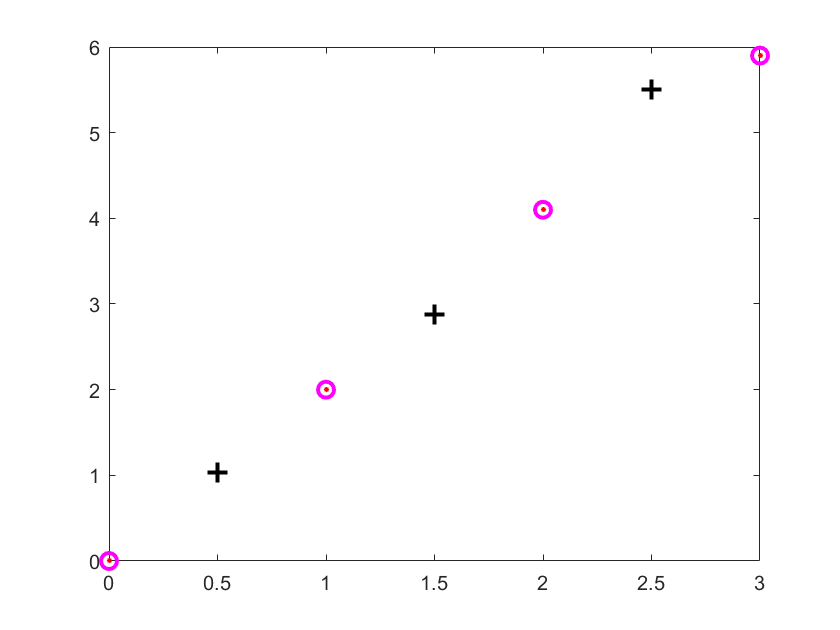

plot(P,T,'*r','MarkerSize',2,'LineWidth',2)
hold on
plot(P,V,'om','MarkerSize',8, 'LineWidth',2)
hold on
plot(P1,Y,'+k','MarkerSize',10, 'LineWidth',2)
hold off